clearvars; clc; close all;

T = 0.001;

q_0 = [0; pi/4; -pi/4; pi/4; 0; 0; 0];
q_dot_0 = zeros(7,1);
q_ddot_0 = zeros(7,1);

robot = KUKA_LBR_IIWA7(q_0, q_dot_0, q_ddot_0);

% kuka = importrobot('iiwa7.urdf'); 
% kuka.DataFormat = 'row';
% ndof = 7;
% 
% bounds_min_position = constraintJointBounds(kuka).Bounds(:,1)';
% bounds_max_position = constraintJointBounds(kuka).Bounds(:,2)';
% bounds_position = double([bounds_min_position;bounds_max_position]);
% 
% bounds_max_velocity = round([deg2rad(100), deg2rad(110), deg2rad(100), deg2rad(130), deg2rad(130), deg2rad(180), deg2rad(180)],4);
% bounds_min_velocity = -bounds_max_velocity;
% bounds_velocity = double([bounds_min_velocity;bounds_max_velocity]);
% 
% bounds_max_acceleration = [300, 300, 300, 300, 300, 300, 300];
% bounds_min_acceleration = -bounds_max_acceleration;  
% bounds_acceleration = double([bounds_min_acceleration;bounds_max_acceleration]);
% 
% robot = {kuka, {bounds_position, bounds_velocity, bounds_acceleration}, ndof, q_0};

poly_0 = [[0; 0; 0.2], [0; 0.1732; 0.1], [0; 0.1732; -0.1], [0; 0; -0.2], [0; -0.1732; -0.1], [0; -0.1732; 0.1]];
center = [0.1; 0.35; 0.8235];

points = [];
n_cycle=2;
for n=1:n_cycle
    for i=1:6
        points = [points, [poly_0(:,i)]];
    end
end
points = [points, poly_0(:,1)]+center;

qs = run_simulation(robot, points, T);

k = 1, norm(ee_position - x) = 0.667561
k = 1, norm(ee_position - x) = 0.666915
k = 1, norm(ee_position - x) = 0.666267
k = 1, norm(ee_position - x) = 0.665615
k = 1, norm(ee_position - x) = 0.664959
k = 1, norm(ee_position - x) = 0.664299
k = 1, norm(ee_position - x) = 0.663635
k = 1, norm(ee_position - x) = 0.662967
k = 1, norm(ee_position - x) = 0.662296
k = 1, norm(ee_position - x) = 0.661620
k = 1, norm(ee_position - x) = 0.660941
k = 1, norm(ee_position - x) = 0.660258
k = 1, norm(ee_position - x) = 0.659570
k = 1, norm(ee_position - x) = 0.658879
k = 1, norm(ee_position - x) = 0.658184
k = 1, norm(ee_position - x) = 0.657484
k = 1, norm(ee_position - x) = 0.656782
k = 1, norm(ee_position - x) = 0.656074
k = 1, norm(ee_position - x) = 0.655363
k = 1, norm(ee_position - x) = 0.654648
k = 1, norm(ee_position - x) = 0.653929
k = 1, norm(ee_position - x) = 0.653206
k = 1, norm(ee_position - x) = 0.652479
k = 1, norm(ee_position - x) = 0.651747
k = 1, norm(ee_position - x) = 0.651012


%simulation(qs)

sim
Program started.
Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)
Target conf [rad] =          0    0.7854   -0.7854    0.7854         0         0         0

Target conf [rad] =    -0.0008    0.7856   -0.7849    0.7877         0   -0.0031         0

Target conf [rad] =    -0.0016    0.7858   -0.7844    0.7899    0.0000   -0.0063         0

Target conf [rad] =    -0.0035    0.7852   -0.7854    0.7922    0.0005   -0.0094         0

Target conf [rad] =    -0.0057    0.7843   -0.7867    0.7945   -0.0026   -0.0126         0

Target conf [rad] =    -0.0064    0.7845   -0.7862    0.7967   -0.0026   -0.0157         0

Target conf [rad] =    -0.0062    0.7853   -0.7843    0.7990   -0.0029   -0.0188         0

Target conf [rad] =    -0.0069    0.7855   -0.7838    0.8013   -0.0029   -0.0220         0

Target conf [rad] =    -0.0087    0.7849   -0.7846    0.8035   -0.0067   -0.0251         0

Target conf [

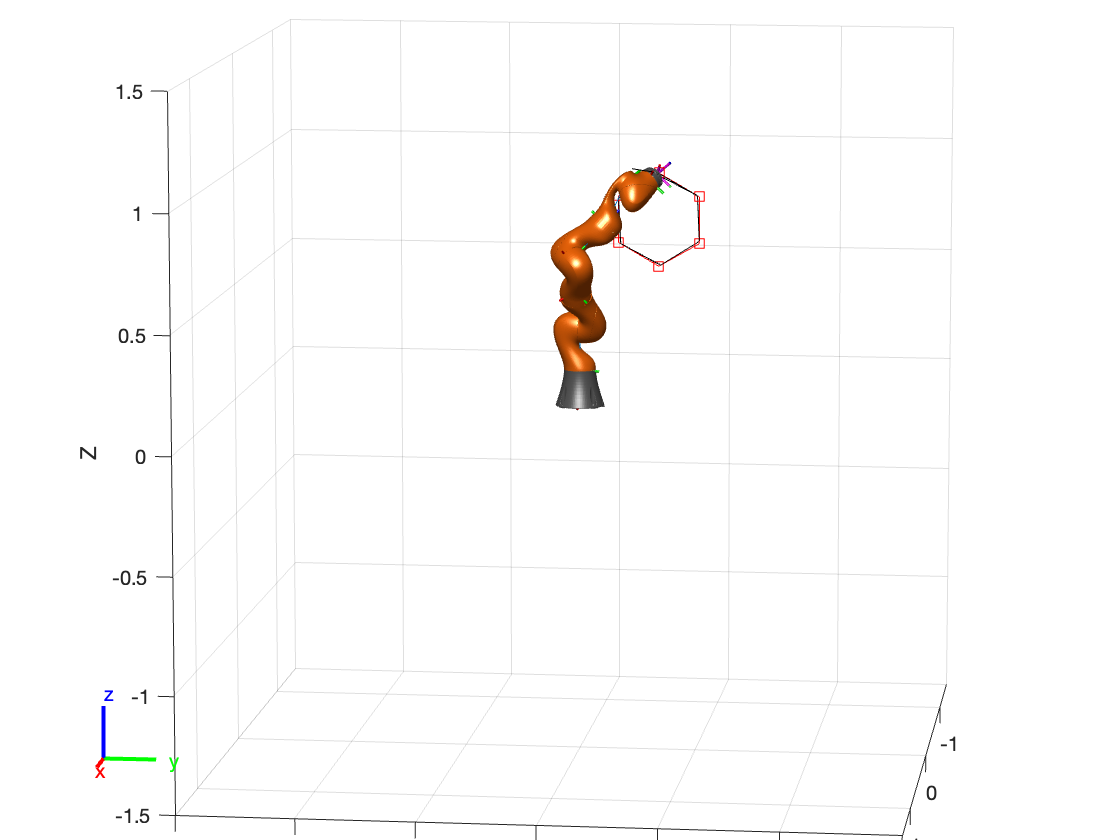

plot_simulation(T, qs, robot, points);